clear
clc

# Foam Wing Structure Calculator V1

#### By James Orendi

## This calculator is only valid for solid wings (e.g. foam). This calculator will not provide a valid answer for spar-and-rib designs.

## UAV Data

Mass_MTOW = 4.87 ; % kg
g = 9.81 ; % m s^-2

addpath([cd,'/Functions'])

## Wing Data

wing_span = 1.8 ; % m
c_r = 0.2196 ; % m
c_k = 0.2196 ; % m
c_t = 0.1098 ; % m
kink_distance_ratio = 0.3333 ; % N/A
wing_dihedral_opp = 0 ; % m
wing_dihedral_kink_opp = 0 ; % m
wing_opp = 0 ; % m
wing_opp_2 = 0.0824 ; % m

## Wing Aerofoil Data

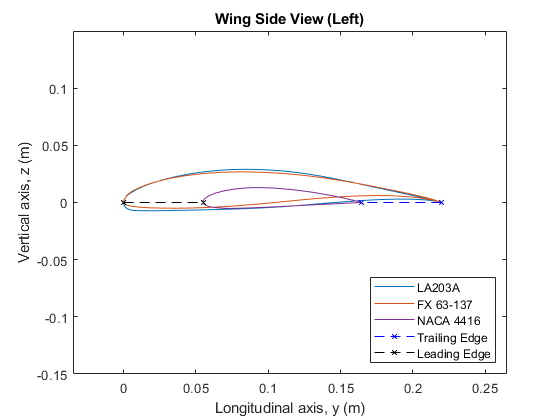

figure
Root_Aerofoil = readmatrix("Aerofoils/LA203A_Combined.txt") ;
Kink_Aerofoil = readmatrix("Aerofoils/FX_63-137_Combined.txt") ;
Tip_Aerofoil = readmatrix("Aerofoils/NACA_4416_Combined.txt") ;
Root_Aerofoil_Positions_x = (c_r)*Root_Aerofoil(:,1) ;
Root_Aerofoil_Positions_y = (c_r)*Root_Aerofoil(:,2) ;
plot(Root_Aerofoil_Positions_x,Root_Aerofoil_Positions_y)
hold on

Kink_Aerofoil_Positions_x = (wing_opp*kink_distance_ratio)+(c_k)*Kink_Aerofoil(:,1) ;
Kink_Aerofoil_Positions_y = (wing_dihedral_opp*kink_distance_ratio)+(c_k)*Kink_Aerofoil(:,2) ;
plot(Kink_Aerofoil_Positions_x,Kink_Aerofoil_Positions_y)

Tip_Aerofoil_Positions_x = (wing_opp*kink_distance_ratio)+(wing_opp_2*(1-kink_distance_ratio))+(c_t)*Tip_Aerofoil(:,1) ;
Tip_Aerofoil_Positions_y = (wing_dihedral_opp)+(c_t)*Tip_Aerofoil(:,2) ;
plot(Tip_Aerofoil_Positions_x,Tip_Aerofoil_Positions_y,'Color',[0.4940 0.1840 0.5560])

leading_edge_line_x = [0, wing_opp*kink_distance_ratio, (wing_opp*kink_distance_ratio)+(wing_opp_2*(1-kink_distance_ratio))] ;
leading_edge_line_y = [0, (wing_dihedral_opp*kink_distance_ratio), (wing_dihedral_opp)] ;
trailing_edge_line_x = [c_r, wing_opp*kink_distance_ratio+c_k, (wing_opp*kink_distance_ratio)+(wing_opp_2*(1-kink_distance_ratio))+c_t] ;
plot(trailing_edge_line_x,leading_edge_line_y, 'b--', 'Marker','x','MarkerSize',5)
plot(leading_edge_line_x,leading_edge_line_y, 'k--','Marker','x','MarkerSize',5)



xlim([-0.035,0.265])
ylim([-0.15,0.15])
title("Wing Side View (Left)")
xlabel("Longitudinal axis, y (m)")
ylabel("Vertical axis, z (m)")
legend("LA203A","FX 63-137","NACA 4416","Trailing Edge","Leading Edge",'Location','Southeast')
hold off

## Wing Structure

### Numerical Method for Aerofoil upper and lower surface

%aerofoil_fit_data = [Root_Aerofoil_Positions_x,Root_Aerofoil_Positions_y] ;

% ASSUMPTION -> Centroid lies upon chord line (negligible y displacement)
% This means a one-to-one function for both upper and lower surfaces

upper_surface_root = c_r*readmatrix("Aerofoils/LA203A_Set_1.txt") ;
lower_surface_root = c_r*readmatrix("Aerofoils/LA203A_Set_2.txt") ;

upper_surface_kink = c_k*readmatrix("Aerofoils/FX_63-137_Set_1.txt") ;
lower_surface_kink = c_k*readmatrix("Aerofoils/FX_63-137_Set_2.txt") ;

upper_surface_tip = c_t*readmatrix("Aerofoils/NACA_4416_Set_1.txt") ;
lower_surface_tip = c_t*readmatrix("Aerofoils/NACA_4416_Set_2.txt") ;

% centroid_root_x_test = mean(Root_Aerofoil_Positions_x) % Distance of centroid from leading edge, m

### Function Call

[A_root,centroid_root_x,I_x_root,I_y_root,J_root,expr_upper_root,expr_lower_root,index1_root,index2_root] = AIJ_aerofoil(upper_surface_root,lower_surface_root) ;
[A_kink,centroid_kink_x,I_x_kink,I_y_kink,J_kink,expr_upper_kink,expr_lower_kink,index1_kink,index2_kink] = AIJ_aerofoil(upper_surface_kink,lower_surface_kink) ;
[A_tip,centroid_tip_x,I_x_tip,I_y_tip,J_tip,expr_upper_tip,expr_lower_tip,index1_tip,index2_tip] = AIJ_aerofoil(upper_surface_tip,lower_surface_tip) ;

disp(['Root Polynomial Order for Upper Surface = ', num2str(index1_root-1)])

Root Polynomial Order for Upper Surface = 10


disp(['Root Polynomial Order for Lower Surface = ', num2str(index2_root-1)])

Root Polynomial Order for Lower Surface = 10



disp(['Kink Polynomial Order for Upper Surface = ', num2str(index1_kink-1)])

Kink Polynomial Order for Upper Surface = 10


disp(['Kink Polynomial Order for Lower Surface = ', num2str(index2_kink-1)])

Kink Polynomial Order for Lower Surface = 10



disp(['Tip Polynomial Order for Upper Surface = ', num2str(index1_tip-1)])

Tip Polynomial Order for Upper Surface = 10


disp(['Tip Polynomial Order for Lower Surface = ', num2str(index2_tip-1)])

Tip Polynomial Order for Lower Surface = 10


### Bending Calculations for Wing Aerofoil

wing_root_twist_moment_arm = abs(centroid_root_x-(c_r/4)) % AC-centroid moment arm, m

wing_root_twist_moment_arm = 0.0330

wing_root_bending_moment = (wing_span/2)*(Mass_MTOW*g/2)

wing_root_bending_moment = 21.4986

wing_root_twist_moment = (wing_root_twist_moment_arm)*(Mass_MTOW*g/2)

wing_root_twist_moment = 0.7874


aerofoil_y_max = max(upper_surface_root(:,2)) ;
aerofoil_y_min = min(lower_surface_root(:,2)) ;
aerofoil_y_range = aerofoil_y_max-aerofoil_y_min ;

syms x
aerofoil_upper_max = double(max(vpasolve(diff(expr_upper_root) == 0,x)))

aerofoil_upper_max = 0.2258

aerofoil_lower_min = double(min(vpasolve(diff(expr_lower_root) == 0,x)))

aerofoil_lower_min = 0.0108


sigma_aerofoil = (wing_root_bending_moment*aerofoil_y_max)/I_x_root % Bending Stress

sigma_aerofoil = 7.5717e+05

tau_aerofoil = wing_root_twist_moment/J_root % Torsion Stress

tau_aerofoil = 1.5972e+04

#### Wing Polynomial Plots

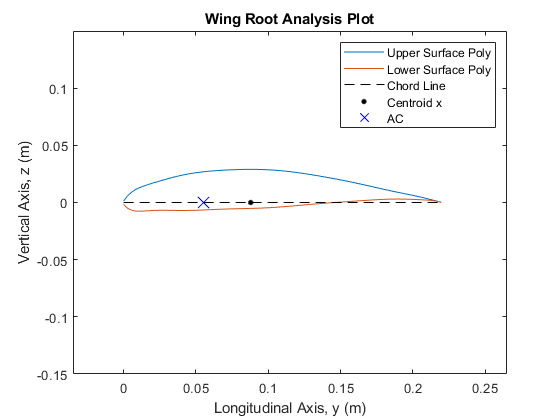

figure
%plot(upper_surface_root(:,1),upper_surface_root(:,2))
fplot(expr_upper_root,[0,c_r])
hold on
%plot(lower_surface_root(:,1),lower_surface_root(:,2))
fplot(expr_lower_root,[0,c_r])
plot([0,c_r],[0,0],'k--')
plot(centroid_root_x,0,'k.','MarkerSize',12)
plot(c_r/4,0,'bx','markersize',12)

% plot(centroid_root_x_test,0,'r.','MarkerSize',12)

% legend("Upper Surface Data","Upper Surface Poly","Lower Surface Data","Lower Surface Poly","Chord Line","Centroid x","AC")
legend("Upper Surface Poly","Lower Surface Poly","Chord Line","Centroid x","AC")

xlim([-0.035,0.265])
ylim([-0.15,0.15])
xlabel('Longitudinal Axis, y (m)')
ylabel('Vertical Axis, z (m)')
title('Wing Root Analysis Plot')

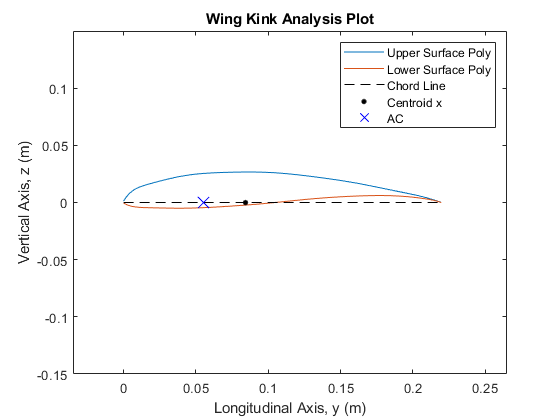


figure
%plot(upper_surface_kink(:,1),upper_surface_kink(:,2))
fplot(expr_upper_kink,[0,c_k])
hold on
%plot(lower_surface_kink(:,1),lower_surface_kink(:,2))
fplot(expr_lower_kink,[0,c_k])
plot([0,c_k],[0,0],'k--')
plot(centroid_kink_x,0,'k.','MarkerSize',12)
plot(c_k/4,0,'bx','markersize',12)

%legend("Upper Surface Data","Upper Surface Poly","Lower Surface Data","Lower Surface Poly","Chord Line","Centroid x","AC")
legend("Upper Surface Poly","Lower Surface Poly","Chord Line","Centroid x","AC")

xlim([-0.035,0.265])
ylim([-0.15,0.15])
xlabel('Longitudinal Axis, y (m)')
ylabel('Vertical Axis, z (m)')
title('Wing Kink Analysis Plot')

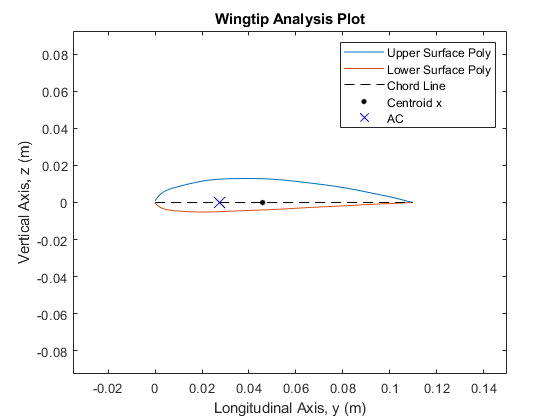


figure
%plot(upper_surface_tip(:,1),upper_surface_tip(:,2))
fplot(expr_upper_tip,[0,c_t])
hold on
%plot(lower_surface_tip(:,1),lower_surface_tip(:,2))
fplot(expr_lower_tip,[0,c_t])
plot([0,c_t],[0,0],'k--')
plot(centroid_tip_x,0,'k.','MarkerSize',12)
plot(c_t/4,0,'bx','markersize',12)

% legend("Upper Surface Data","Upper Surface Poly","Lower Surface Data","Lower Surface Poly","Chord Line","Centroid x","AC")
legend("Upper Surface Poly","Lower Surface Poly","Chord Line","Centroid x","AC")

xlim([-0.035,0.15])
ylim([-0.0925,0.0925])
xlabel('Longitudinal Axis, y (m)')
ylabel('Vertical Axis, z (m)')
title('Wingtip Analysis Plot')

### Estimations for Pure EPP Wing Bending

TS_EPP = (40/45) * 0.46e6 % Pa, Tensile Strength of Expanded Polypropelene

TS_EPP = 4.0889e+05

FS_EPP = (40/45) * 0.54e6 % Pa, Flexural Strength

FS_EPP = 480000

E_EPP = (40/45) * 14.5e6 % Pa, Flexural Modulus.

E_EPP = 1.2889e+07

% These values are linear interpolations of the 45g/l EPP elastic modulus data


% Assumption, half of the lift is generated as a point force on the wingtip
wing_l_array = linspace(0,wing_span/2,100) ;
wing_l_array_2 = linspace(-wing_span/2,wing_span/2,200) ;

% Single Material Wing Bending
delta_B = ((Mass_MTOW*g/2).*((wing_l_array).^3))./(3*E_EPP*I_x_root) ; % m
disp(['Wingtip deflection estimated ', num2str(max(delta_B)*1000), ' mm'])

Wingtip deflection estimated 546.8105 mm



wing_moment = ((Mass_MTOW*9.81)/2)*wing_l_array ;
wing_stress = (wing_moment*max([aerofoil_upper_max,aerofoil_lower_min]))/I_x_root ;
wing_stress_max = max(wing_stress)

wing_stress_max = 5.8953e+06

wing_safety_factor = 3

wing_safety_factor = 3

wing_stress_safety = wing_safety_factor*wing_stress_max

wing_stress_safety = 1.7686e+07


if TS_EPP < wing_stress_safety
    disp('Stress is higher than safety factored strength desired, >>> UNSAFE <<<')
else
    disp('Stress is below safety factored strength desired, SAFE')
end

Stress is higher than safety factored strength desired, >>> UNSAFE <<<


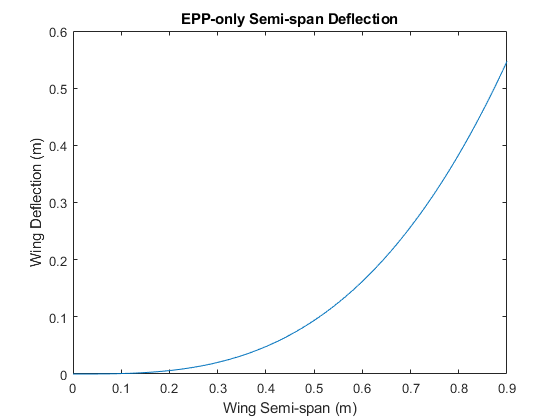


% gamma_0 = (4*Mass_MTOW*g)/(pi*Takeoff_air_density*Cruise_speed_aircraft*wing_span)
% l_ellip = ((gamma_0).*sqrt(1-((2*wing_l_array_2/(wing_span)).^2)));
% 
% figure()
% plot(wing_l_array_2,l_ellip)

figure()
plot(wing_l_array,delta_B)
xlabel("Wing Semi-span (m)")
ylabel("Wing Deflection (m)")
title("EPP-only Semi-span Deflection")

%xlim([0,1])
%ylim([0,1])

### Estimations for EPP-CFRP Wing Bending

TS_CFRP = 400e6 % Pa, Tensile Strength of Carbon-Fibre Reinforced Polymer

TS_CFRP = 400000000

E_CFRP = 40e9 % Pa, Young's Modulus of Carbon-Fibre Reinforced Polymer

E_CFRP = 4.0000e+10


E_ratio = (E_CFRP/E_EPP) % Ratio of Young's Moduli of CFRP and EPP

E_ratio = 3.1034e+03


CFRP_strip_upper_width = 6/1000 % m

CFRP_strip_upper_width = 0.0060

CFRP_strip_upper_height = 1/1000 % m

CFRP_strip_upper_height = 1.0000e-03

CFRP_strip_upper_offset = 27/1000 % m

CFRP_strip_upper_offset = 0.0270

CFRP_strip_upper_x_data = [centroid_root_x-CFRP_strip_upper_width/2,centroid_root_x-CFRP_strip_upper_width/2,centroid_root_x+CFRP_strip_upper_width/2,centroid_root_x+CFRP_strip_upper_width/2,centroid_root_x-CFRP_strip_upper_width/2] ;
CFRP_strip_upper_y_data = [-CFRP_strip_upper_height/2,CFRP_strip_upper_height/2,CFRP_strip_upper_height/2,-CFRP_strip_upper_height/2,-CFRP_strip_upper_height/2] + CFRP_strip_upper_offset ;

CFRP_strip_lower_width = 6/1000 % m

CFRP_strip_lower_width = 0.0060

CFRP_strip_lower_height = 1/1000 % m

CFRP_strip_lower_height = 1.0000e-03

CFRP_strip_lower_offset = -4/1000 % m

CFRP_strip_lower_offset = -0.0040

CFRP_strip_lower_x_data = [centroid_root_x-CFRP_strip_lower_width/2,centroid_root_x-CFRP_strip_lower_width/2,centroid_root_x+CFRP_strip_lower_width/2,centroid_root_x+CFRP_strip_lower_width/2,centroid_root_x-CFRP_strip_lower_width/2] ;
CFRP_strip_lower_y_data = [-CFRP_strip_lower_height/2,CFRP_strip_lower_height/2,CFRP_strip_lower_height/2,-CFRP_strip_lower_height/2,-CFRP_strip_lower_height/2] + CFRP_strip_lower_offset ;

CFRP_I_upper = (CFRP_strip_upper_width*(CFRP_strip_upper_height^3)/12) + (CFRP_strip_upper_width*CFRP_strip_upper_height)*(CFRP_strip_upper_offset^2) ;
CFRP_I_lower = (CFRP_strip_lower_width*(CFRP_strip_lower_height^3)/12) + (CFRP_strip_lower_width*CFRP_strip_lower_height)*(CFRP_strip_lower_offset^2) ;

aerofoil_I_composite_total = I_x_root + (CFRP_I_upper+CFRP_I_lower)*(E_ratio-1) ;

wing_stress_composite = (wing_moment*max([aerofoil_upper_max,aerofoil_lower_min]))/I_x_root ;
wing_stress_composite_max = max(wing_stress_composite) ;
wing_safety_factor_composite = 3 ;
wing_stress_safety_composite = wing_safety_factor_composite*wing_stress_composite_max ;

if TS_CFRP < wing_stress_safety_composite
    disp('Stress is higher than safety factored strength desired, >>> UNSAFE <<<')
else
    disp('Stress is below safety factored strength desired, SAFE')
end

Stress is below safety factored strength desired, SAFE


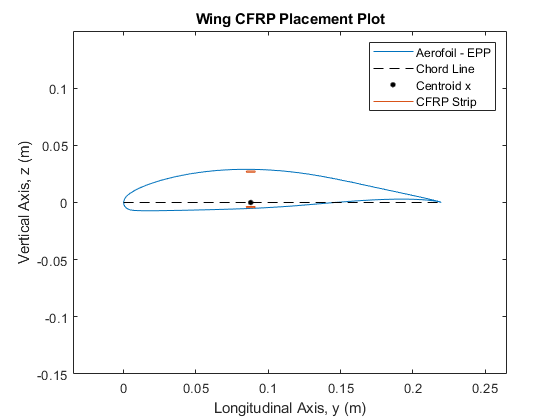


figure
plot([upper_surface_root(:,1),lower_surface_root(:,1)],[upper_surface_root(:,2),lower_surface_root(:,2)],'color',[0 0.4470 0.7410])
hold on
plot([0,c_r],[0,0],'k--')
plot(centroid_root_x,0,'k.','MarkerSize',12)
plot(CFRP_strip_upper_x_data,CFRP_strip_upper_y_data,'color',[0.8500 0.3250 0.0980])
plot(CFRP_strip_lower_x_data,CFRP_strip_lower_y_data,'color',[0.8500 0.3250 0.0980])
legend("Aerofoil - EPP","","Chord Line","Centroid x","CFRP Strip")

xlim([-0.035,0.265])
ylim([-0.15,0.15])
xlabel('Longitudinal Axis, y (m)')
ylabel('Vertical Axis, z (m)')
title('Wing CFRP Placement Plot')


% Composite Wing Bending
delta_B_composite = ((Mass_MTOW*g/2).*((wing_l_array).^3))./(3*E_EPP*aerofoil_I_composite_total) ; % m
disp(['Wingtip deflection estimated ', num2str(max(delta_B_composite)*1000), ' mm'])

Wingtip deflection estimated 30.6478 mm


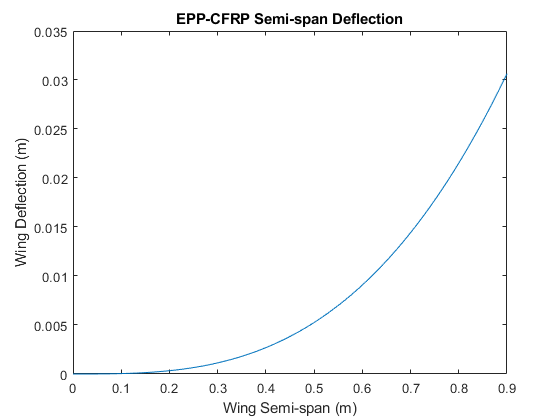


figure()
plot(wing_l_array,delta_B_composite)
xlabel("Wing Semi-span (m)")
ylabel("Wing Deflection (m)")
title("EPP-CFRP Semi-span Deflection")